## Thomas algorithm - Ex. 5.3

clear all;
close all;
clc;

Consider the tridiagonal matrix $A \in R^{10 \times 10}$

n = 10;

a = [1:10]';
b = [10:19]';
c = [102:111]';

A = spdiags([c a b], -1:1, n, n)

A =    (1,1)        1
   (2,1)      102
   (1,2)       11
   (2,2)        2
   (3,2)      103
   (2,3)       12
   (3,3)        3
   (4,3)      104
   (3,4)       13
   (4,4)        4
   (5,4)      105
   (4,5)       14
   (5,5)        5
   (6,5)      106
   (5,6)       15
   (6,6)        6
   (7,6)      107
   (6,7)       16
   (7,7)        7
   (8,7)      108
   (7,8)       17
   (8,8)        8
   (9,8)      109
   (8,9)       18
   (9,9)        9
  (10,9)      110
   (9,10)      19
  (10,10)      10


full(A)

ans =      1    11     0     0     0     0     0     0     0     0
   102     2    12     0     0     0     0     0     0     0
     0   103     3    13     0     0     0     0     0     0
     0     0   104     4    14     0     0     0     0     0
     0     0     0   105     5    15     0     0     0     0
     0     0     0     0   106     6    16     0     0     0
     0     0     0     0     0   107     7    17     0     0
     0     0     0     0     0     0   108     8    18     0
     0     0     0     0     0     0     0   109     9    19
     0     0     0     0     0     0     0     0   110    10


Then, consider the linear system $Ax = b$ such that $x = ones(10,1)$

x = ones(10, 1);

b = A*b

b =          131
        1186
        1338
        1496
        1660
        1830
        2006
        2188
        2376
        2170


### Implement the Thomas algorithm and solve the linear system

With the Thomas algorithm we want to decompose $A$ into $L$ and $U$, where:

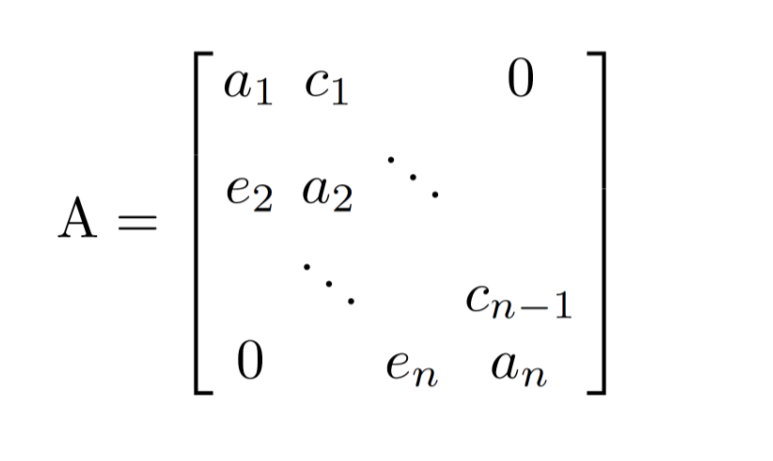

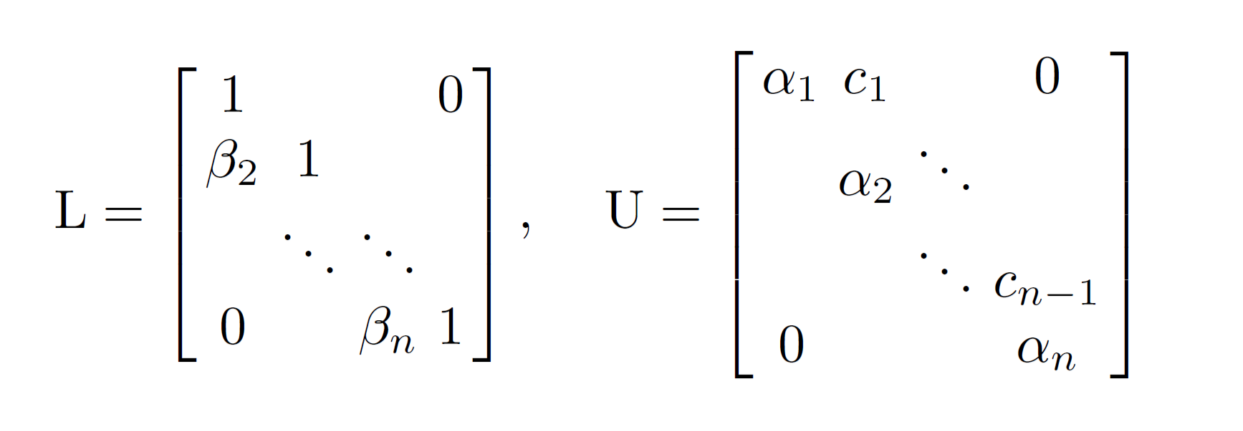

And the components are computed as:


$$\alpha_1 = a_1, \\
\beta_i = \frac{e_i}{\alpha_{i-1}}, \\
\alpha_i = a_i - \beta_i c_{i-1}
$$


[L, U] = thomas(A)

L =     1.0000         0         0         0         0         0         0         0         0         0
  102.0000    1.0000         0         0         0         0         0         0         0         0
         0   -0.0920    1.0000         0         0         0         0         0         0         0
         0         0   25.3438    1.0000         0         0         0         0         0         0
         0         0         0   -0.3226    1.0000         0         0         0         0         0
         0         0         0         0   11.1385    1.0000         0         0         0         0
         0         0         0         0         0   -0.6643    1.0000         0         0         0
         0         0         0         0         0         0    6.1265    1.0000         0         0
         0         0         0         0         0         0         0   -1.1336    1.0000         0
         0         0         0         0         0         0         0         0    3.7

U = 	1.0e+03 *

    0.0010    0.0110         0         0         0         0         0         0         0         0
         0   -1.1200    0.0120         0         0         0         0         0         0         0
         0         0    0.0041    0.0130         0         0         0         0         0         0
         0         0         0   -0.3255    0.0140         0         0         0         0         0
         0         0         0         0    0.0095    0.0150         0         0         0         0
         0         0         0         0         0   -0.1611    0.0160         0         0         0
         0         0         0         0         0         0    0.0176    0.0170         0         0
         0         0         0         0         0         0         0   -0.0961    0.0180         0
         0         0         0         0         0         0         0         0    0.0294    0.0190
         0         0         0         0         0         0         0     


y = L \ b

y = 	1.0e+04 *

    0.0131
   -1.2176
    0.0218
   -0.4035
    0.0358
   -0.2160
    0.0571
   -0.1311
    0.0890
   -0.1160


x = U \ y

x =    10.0000
   11.0000
   12.0000
   13.0000
   14.0000
   15.0000
   16.0000
   17.0000
   18.0000
   19.0000



comp_A = L*U

comp_A =     1.0000   11.0000         0         0         0         0         0         0         0         0
  102.0000    2.0000   12.0000         0         0         0         0         0         0         0
         0  103.0000    3.0000   13.0000         0         0         0         0         0         0
         0         0  104.0000    4.0000   14.0000         0         0         0         0         0
         0         0         0  105.0000    5.0000   15.0000         0         0         0         0
         0         0         0         0  106.0000    6.0000   16.0000         0         0         0
         0         0         0         0         0  107.0000    7.0000   17.0000         0         0
         0         0         0         0         0         0  108.0000    8.0000   18.0000         0
         0         0         0         0         0         0         0  109.0000    9.0000   19.0000
         0         0         0         0         0         0         0         0  


comp_b = round(A*x)

comp_b =          131
        1186
        1338
        1496
        1660
        1830
        2006
        2188
        2376
        2170


b

b =          131
        1186
        1338
        1496
        1660
        1830
        2006
        2188
        2376
        2170



if comp_b == b
    fprintf("OK");
else
    fprintf("ERROR");
end

OK

function [L, U] = thomas(A)
    n = length(A);

    L = diag(diag(ones(n)));
    
    d = full(diag(A,1)); % use of full otherwise d will be stored in sparse mode
    d = [0; d]; % padding in order to be consistent with the vector dimension
    
    U = spdiags([zeros(n,1) zeros(n,1) d], -1:1, n, n);
    
    U(1,1) = A(1,1);
    
    for i = 2:n
        L(i,i-1) = A(i,i-1) / U(i-1,i-1);
        U(i,i) = A(i,i) - L(i,i-1)*A(i-1,i);
    end
    
    U = full(U);
end